% load data/iphone_data3.mat;
% 
% Fs = 100;
% AccelerationReadings = table2array(Acceleration);
% AngularVelocityReadings = table2array(AngularVelocity);
% MagneticFieldReadings = table2array(MagneticField);

T = readtable('/Users/ivankcl/Desktop/ASTRI/code/data/calibration.csv.nosync.csv')

T = 7525×35 table
    PacketCounter    SampleTimeFine      Acc_X        Acc_Y      Acc_Z       Gyr_X        Gyr_Y        Gyr_Z       Mag_X       Mag_Y       Mag_Z     VelInc_X     VelInc_Y     VelInc_Z    OriInc_q0    OriInc_q1    OriInc_q2    OriInc_q3     Pressure     Quat_q0    Quat_q1      Quat_q2      Quat_q3      Roll       Pitch         Yaw       Mat_1__1_    Mat_2__1_    Mat_3__1_    Mat_1__2_    Mat_2__2_    Mat_3__2_    Mat_1__3_


AccelerationReadings = fillmissing(table2array(T(:,3:5)),'previous');
AngularVelocityReadings = fillmissing(table2array(T(:,6:8)), 'previous');
MagneticFieldReadings = fillmissing(table2array(T(:, 9:11)),'previous');

f1 = AccelerationReadings(:,1);
f2 = AccelerationReadings(:,2);
f3 = AccelerationReadings(:,3);

size(AccelerationReadings)

ans =         7525           3



Fs = 40;
decim = 1;

fuse = ahrsfilter('SampleRate', Fs, 'DecimationFactor', decim, 'AccelerometerNoise', 0.000016, 'GyroscopeNoise', 0.00000123456, 'MagnetometerNoise', 1e-14);

q = fuse(AccelerationReadings, AngularVelocityReadings, MagneticFieldReadings);

time = (0:decim:size(AccelerationReadings, 1)-1)/Fs;


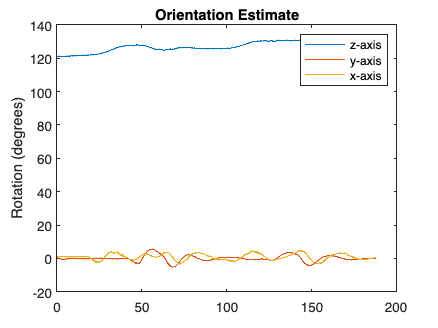

plot(time,eulerd(q,'ZYX','frame'))
title('Orientation Estimate')
legend('z-axis', 'y-axis', 'x-axis')
ylabel('Rotation (degrees)')

y = euler(q, "ZXY", 'frame');
psi = y(:,1);           %  rad
theta = y(:,2);         %  rad
phi = y(:,3);           %  rad   

for k = 1:length(psi)
    R1 = [ cos(psi(k)), sin(psi(k)), 0;                          
          -sin(psi(k)), cos(psi(k)), 0;              
           0, 0, 1];
    R2 = [cos(theta(k)), 0, -sin(theta(k));       
          0, 1, 0;
          sin(theta(k)), 0, cos(theta(k))];    
    R3 = [1, 0, 0;                               
          0, cos(phi(k)), sin(phi(k));       
          0, -sin(phi(k)), cos(phi(k))];
    F123 = ((R3*R2*R1)')*[f1(k), f2(k), f3(k)]';        %  m/s^2    
    F1(k,1) = F123(1);                                  %  m/s^2
    F2(k,1) = F123(2);                                  %  m/s^2
    F3(k,1) = F123(3);                                  %  m/s^2
end

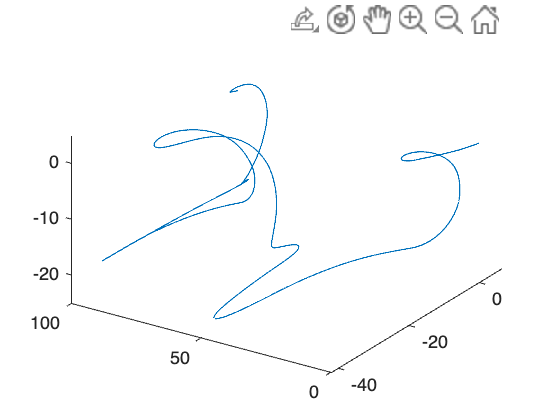

x1ddot = F1 - mean(F1);        %  m/s^2
x2ddot = F2 - mean(F2);        %  m/s^2
x3ddot = F3 - mean(F3);        %  m/s^2

% x1ddot(1:100,1)
%  Numerically integrate the space-fixed acceleration components to obtain 
%  the velocity components of the iPhone's IMU:

time = (0:1:size(x3ddot, 1)-1)/Fs;

x1dot = cumtrapz(time, x1ddot);       %  m/s
x2dot = cumtrapz(time, x2ddot);      	%  m/s
x3dot = cumtrapz(time, x3ddot);    	%  m/s

%  Numerically integrate the space-fixed velocity components to obtain the
%  components of displacement:

x1 = cumtrapz(time, x1dot);    	%  m
x2 = cumtrapz(time, x2dot);    	%  m
x3 = cumtrapz(time, x3dot);    	%  m

% x1(1:100,1)
plot3(x1, x2, x3)